## Settings

clear;

## Background

### Moments

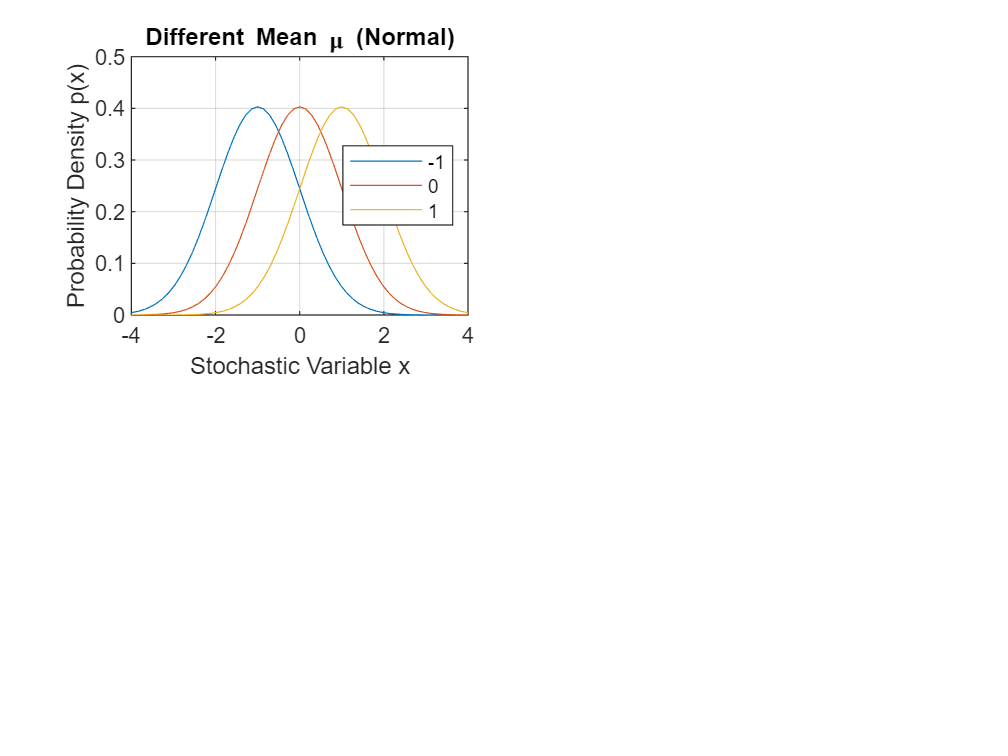

[x,p] = gnorm(-1:1:1,1,2);
m = moment(1,x,p);
myplot(1,x,p);
title("Different Mean \mu (Normal)");
legend("-1","0","1","Location","east");

[x,p] = gnorm(0,[0.5 1 2],2);
m = moment(2,x,p)

m =     0.2500    1.0000    4.0000


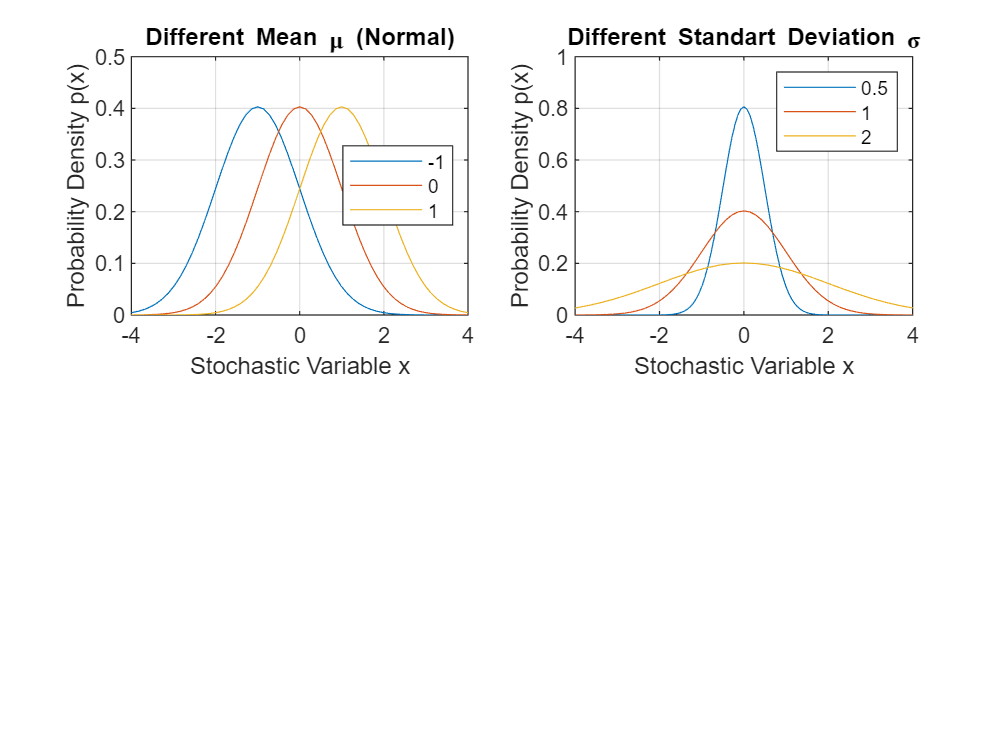

myplot(2,x,p);
title("Different Standart Deviation \sigma");
legend("0.5","1","2");

alpha = [5 3 2];
beta2 = [2 3 5];
[x,p] = beta(-4,4,alpha,beta2);
m1 = moment(1,x,p);
[x,p] = beta(-4-m1,4-m1,alpha,beta2);
m = moment(1,x,p);
m2 = moment(2,x,p);
[x,p] = beta((-4-m1)./sqrt(m2),(4-m1)./sqrt(m2),alpha,beta2);
m = moment(2,x,p);
s = moment(3,x,p)

s =    -0.4066    0.0000    0.4066


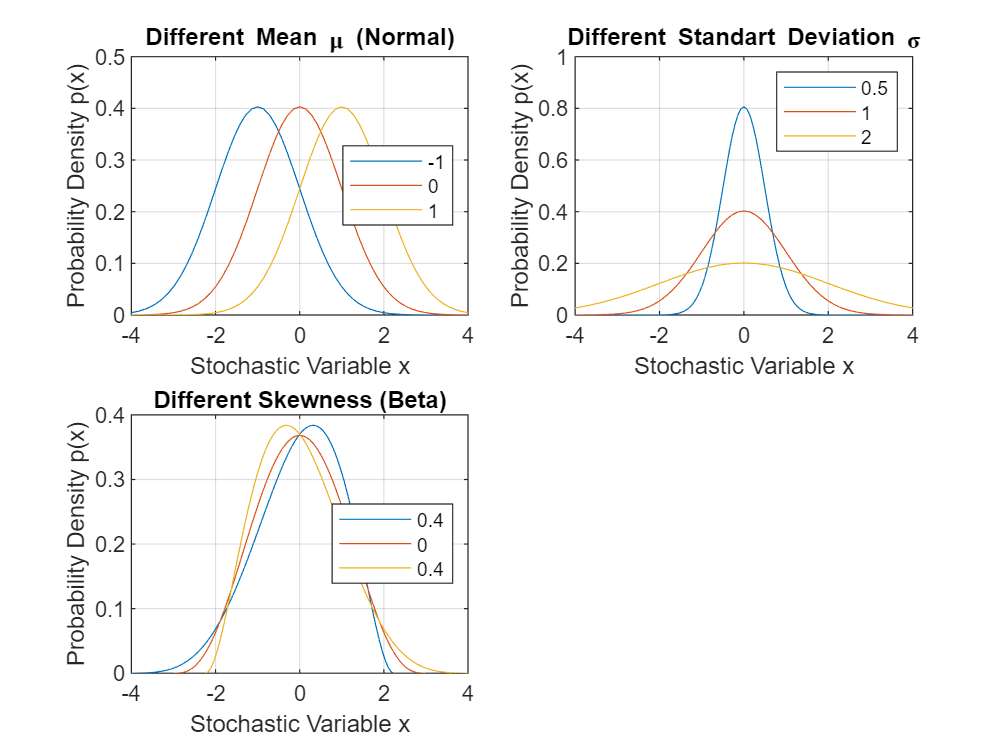

myplot(3,x,p);
title("Different Skewness (Beta)");
legend("0.4","0","0.4","Location","east");

beta4 = [6 2 1.4];
[x,p] = gnorm(0,1,beta4);
m = moment(2,x,p);
[x,p] = gnorm(0,1./sqrt(m),beta4);
m = moment(2,x,p);
k = moment(4,x,p)

k =     2.0000    3.0000    3.9935


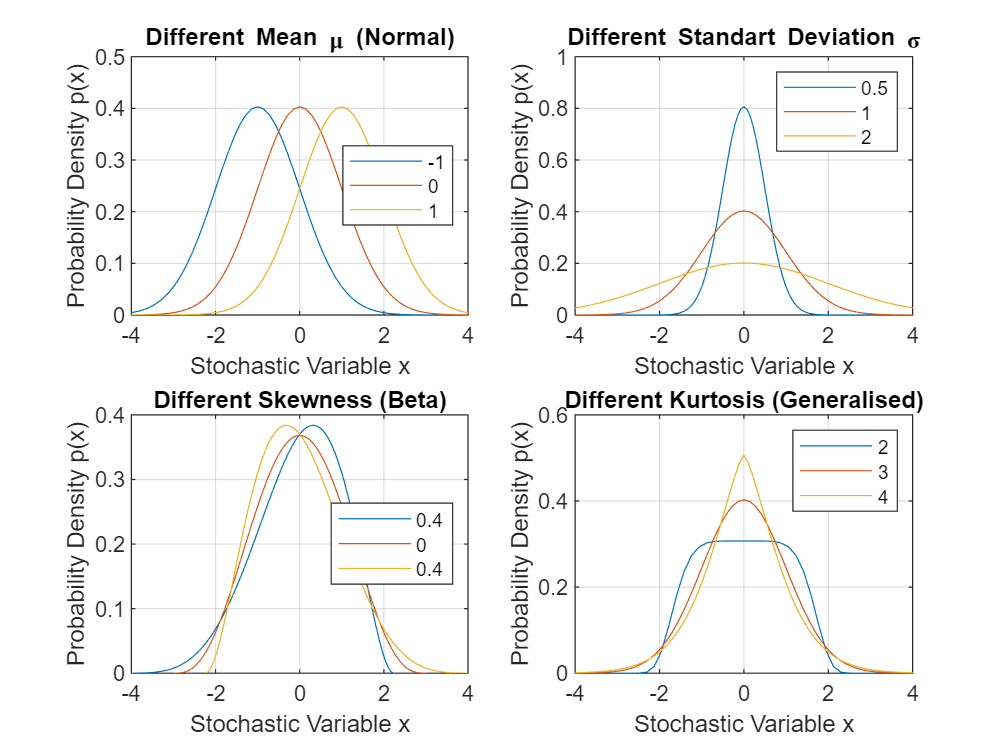

myplot(4,x,p);
title("Different Kurtosis (Generalised)");
legend("2","3","4");

function [x,p]=gnorm(mu,alpha,beta)
% genseralised normal distribution with mu, alpha and beta
    alpha = alpha * sqrt(2);
    x = (-5:0.1:5)'; 
    p = exp(-abs(x).^beta);
    x = mu + x * alpha;
    p = p./mean(p)./(10.*alpha);
end

function [x,p]=beta(a,b,alpha,beta)
% beta distribution with alpha+1 and beta+1
% scaled to [a,b]
    x = (0:0.01:1)'; 
    p = x.^alpha .* (1-x).^beta;
    x = a + (b-a).*x;
    p = p./mean(p)./(b-a);
end

function [m]=moment(n,x,p)
% calculate the nth moment
    m = mean(x.^n.*p).*(x(end,:)-x(1,:));
end

function myplot(n,x,p)
% plot a distribution
   subplot(2,2,n);
   plot(x,p);
   xlabel("Stochastic Variable x");
   ylabel("Probability Density p(x)");
   xlim([-4 4]);
   grid;
end
